## Least Square Fit (LSF) polynomials

Given the table, 


$$\begin{array}{c|c|c|c|c}
x & x_{1} & x_{2} & \cdots & x_{N+1}\\ \hline
f(x) & f\left(x_{1}\right) & f\left(x_{2}\right) & \cdots & f\left(x_{N+1}\right)
\end{array}$$


where, wlog, we can assume $a = x_{1} < x_{2} < \dots < x_{N+1} = b$ so, in particular, these points form a *partition *$\mathcal{P} = \left\{x_{1}, x_{2},\dots,x_{N+1}\right\}$ of the interval $I=[a,b]$. Given another function, $g(x)$, defined in the inteval $I = [a,b]$, we introduce the "distance" $E_{\mathcal{P}}(f,g)$ as


$$E_{\mathcal{P}}(f,g) := \sqrt{\sum_{i=1}^{N+1} \left(f\left(x_{i}\right) - g(x_{i})\right)^{2}},$$


 and we look for a *polynomial* $P_{n}\in\mathbb{R}_{n}[x]$ of degree $n$, $n\le N$, $P_{n}(x) = p_{1}x^{n} + p_{2} x^{n-1} + p_{3} x^{n-2} + \dots + p_{n} x + p_{n+1}$s.t., 


$$E_{\mathcal{P}}\left(f, P_{n}\right) \le E_{\mathcal{P}}\left(f, Q_{n}\right) 
%\sqrt{\sum_{i=1}^{N+1} \left(f\left(x_{i}\right) - P_{n}(x_{i})\right)^{2}} \le \sqrt{\sum_{i=1}^{N+1} \left(f\left(x_{i}\right) - Q_{n}(x_{i})\right)^{2}},$$


for all polynomials $Q_{n}\in\mathbb{R}_{n}[x]$, $Q_{n}(x) = q_{1}x^{n} + q_{2} x^{n-1} + q_{3} x^{n-2} + \dots + q_{n} x + q_{n+1}$, of degree $n \le N$. The polynomials $P_{n}$, $n=1,2,\dots,N$ are called the polynomials of the *least square approximation, *or of the *least square fit *(lsf) of degree $n$. Notably, when $n = N$,  $P_{N}$ is the *interpolation polynomial*, and satisfies


$$P_{N-1}(x_{i}) = f\left(x_{i}\right), \qquad i=1,\dots,N+1.$$


In Matlab the coefficients of the polynomial of the lsf polynomial can be computed using the function `polyfit`:

Later, to evaluate these polynomial in a set of abscisses, we use the function `polyval`. For example, 

**Example. **Let us consider the function

$f(x) = \mathrm{e}^{x/2}\sin(2x)
%f(x) = \frac{1}{1 + x^{2}}
%f(x) = \frac{1}{1 + 25 x^{2}}
$,

on the interval $-1\le x\le 1$, and a sample of points given by the abscisses $x_{i} = -1 + 0.2(i-1)$, and their corresponding values $y=f(y_{i})$, $i=1,\dots,N=11$.

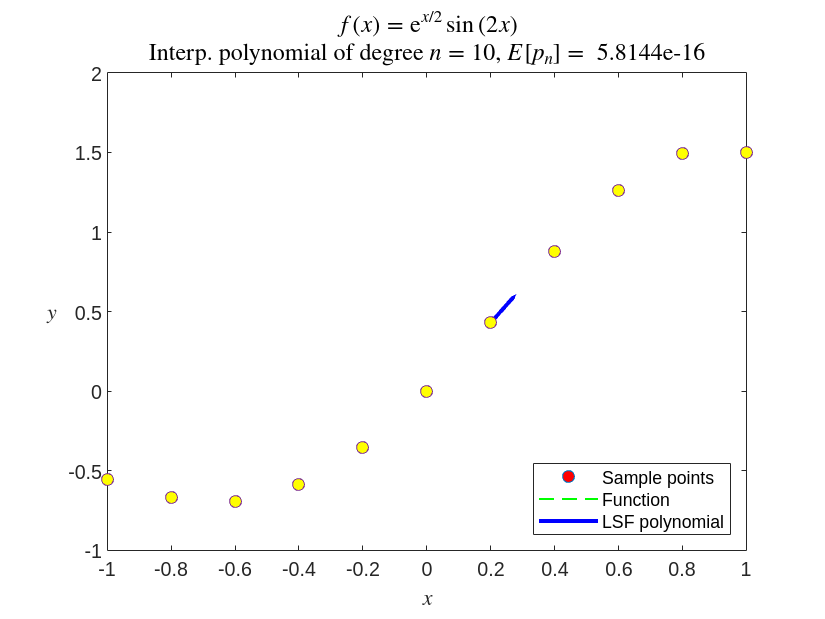

clearvars
close all

a = -1; b = 1; N = 10; delta = 0.01; M = ceil((b-a)/delta); n = 10;

f = @(x) exp(x/2).*sin(2*x); 
myFunction = '$$f(x) = \mathrm{e}^{x/2}\sin\left(2x\right)$$';

%f = @(x) 1./(1+x.^2);
%myFunction = '$$f(x) = \frac{1}{1 + x^{2}}$$';

%f = @(x) 1./(1+25*x.^2); %Runge phenomenon
%myFunction = '$$f(x) = \frac{1}{1 + x^{2}}$$';

xN = linspace(a, b, N+1); fN = f(xN);
xM = linspace(a, b, M+1); fM = f(xM);


%Plot sample points
plot(xN, fN, 'o', 'MarkerFaceColor','red', 'MarkerSize', 6)
hold on

%Plot the function
plot(xM,fM,'--','color','green','LineWidth',1);

%LSF polynomial: polyfit (for n = N: interpolation polynomial)
pn = polyfit(xN, fN, n);

%p(1) = p(1) + 0.01;  %Test: change a bit one of the coefficients

%Plot
pM = polyval(pn, xM);              
pN = polyval(pn, xN);

plot(xM,pM,'-','Color','blue','LineWidth', 2)
plot(xN,pN,'o','MarkerFaceColor','yellow','MarkerSize',6)

for i=1:length(xN)  %to plot the "error" vertical segments
    line=[xN(i), fN(i);
          xN(i), pN(i)];
    plot(line(:,1), line(:,2),'-','color','black','lineWidth',2)
end
lsfError = norm(pN-fN,2);    %LSF-Error

if n < N
    typeOfPolynomial = 'LSF polynomial';
else
    typeOfPolynomial = 'Interp. polynomial';
end

set(gcf,'defaultTextInterpreter','LaTeX')
title({myFunction, ...
    [typeOfPolynomial, ...
    ' of degree $n = $', num2str(n),...
    ', $E[p_{n}] = $ ',num2str(lsfError)]}, ...
    'FontSize',12)
xlabel('$$x$$')
ylabel('$$y$$','rot',360)
legend('Sample points', 'Function', 'LSF polynomial',...
    'Location','southEast')
hold off

fprintf('degree: %d, E[pn] =  %.4e\n', n, lsfError)

degree: 10, E[pn] =  5.8144e-16
